Data Science (Prof. Neff)                    Abgabedatum 01.12.2020

Aufgaben zur schließenden Statistik

Gruppe 6:    Benjamin Hamm (2060696), Jan Klotter (2060690),

                    Anna Kuhn (2051063), Michael Schulze (2061282)

# 1. Konfidenzintervalle

clear
%Messwerte einlesen
data_Bueroklammer = readtable("Lebensdauer_Bueroklammer.csv")

data_Bueroklammer = 75×1 table
    Zyklen
    ______

       9  
      61  
       3  
       2  
       4  
       7  
      25  
      16  
      97  
       4  
       5  
      50  
       2  
       2  
      13  
      17  


data_Viskositaet = readtable("Gruppe_6_Viskositaet.csv")

data_Viskositaet = 10×4 table
    Michael    Benjamin      Jan        Anna  
    _______    ________    _______    ________

    0.84911     2.4133      1.7876      0.3821
     1.3413     2.6144     0.74632     0.27931
     1.3276     2.8602      2.2345      1.3273
    0.88486     2.3239     0.53069     0.62119
    0.96083    0.80163      1.2569     0.22345
     1.4301     1.1061      1.6792    0.093011
     1.5731    0.57315     0.74632      1.3172
    0.97536     1.9664      1.1173      1.3977
     1.5362    0.71504     0.69828     0.27931
     1.1564    0.92732      1.3966     0.45249


## 1a) Darstellen der Daten

%Plotten, Histogramm, etc?

%Statistische Größen bestimmen
mittelwert = mean(data_Bueroklammer.Zyklen)

mittelwert = 15.6133

Median = median(data_Bueroklammer.Zyklen)

Median = 11

Spannweite = range(data_Bueroklammer.Zyklen)

Spannweite = 116

Interquartilsabstand = iqr(data_Bueroklammer.Zyklen)

Interquartilsabstand = 12.5000

Standardabw = std(data_Bueroklammer.Zyklen)

Standardabw = 21.6407

minwert = min(data_Bueroklammer.Zyklen)

minwert = 1

maxwert = max(data_Bueroklammer.Zyklen)

maxwert = 117


%x-Daten, Anzahl Datenwerte etc.
anzahl = length(data_Bueroklammer.Zyklen)

anzahl = 75

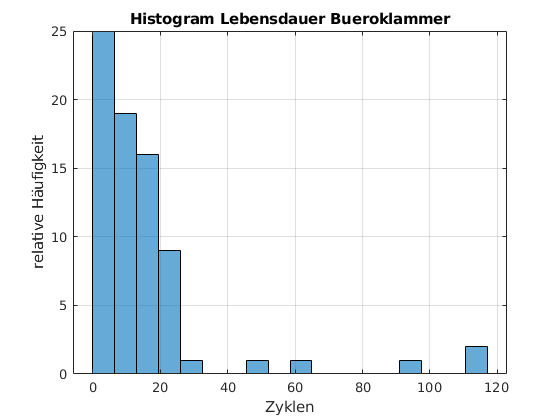

x = (min(data_Bueroklammer.Zyklen)-2:0.1:max(data_Bueroklammer.Zyklen)+2);

figure(1)
histogram(data_Bueroklammer.Zyklen,2*round(sqrt(anzahl)))
grid on
title('Histogram Lebensdauer Bueroklammer')
xlabel('Zyklen')
ylabel('relative Häufigkeit')

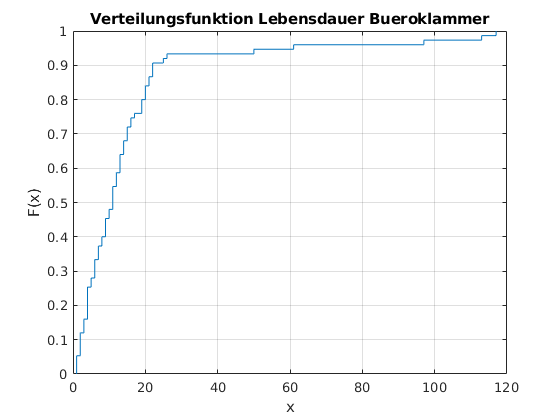


figure(2)
cdfplot(data_Bueroklammer.Zyklen)
title('Verteilungsfunktion Lebensdauer Bueroklammer')
grid on

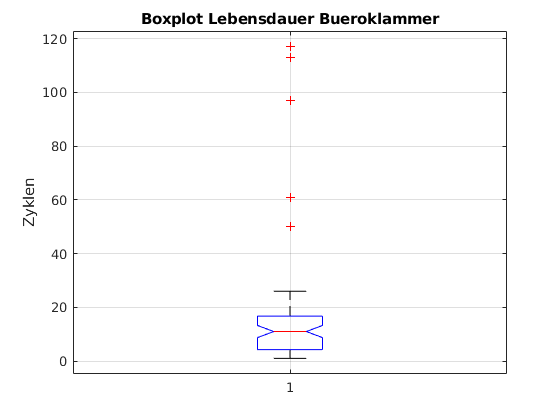


figure(3)
boxplot(data_Bueroklammer.Zyklen, "Notch","on")
title('Boxplot Lebensdauer Bueroklammer')
ylabel('Zyklen')
%set(gca,'ytick',0:10:120)
grid on

## 1b) Konfidenzintervalle

%für Mittelwert anhand einer Normalverteilung


%für Mittelwert anhand einer t-Verteilung


%für einen geeigneten Parameter einer weiteren Verteilung
%z. B. Weibull (Lebensdauer)


%für Mittelwert oder Median im Bootstrap-Verfahren


## 1c) Ergebnisse darstellen und Diskussion

%Plotten der Verteilungen


%Welche Verteilung ist für unsere beiden Datensätze geeignet?
% z. B. Weibull für Büroklammer und Normal für Viskosität
%Begründen!


# 2. Hypothesentests

%Messwerte einlesen
data_cholesterin = readtable("cholesterinsenker.csv")

data_cholesterin = 10×2 table
     A      B 
    ___    ___

      0    -22
    -27    -14
    -16    -15
    -13    -32
     -6    -22
    -27    -34
     -5    -38
    -22    -16
     -9    -25
     -3    -26


## 2a) Darstellen der Daten und Nullhypothese

%Plotten, Histogramm, etc?

%Nullhypothese

## 2b) Test unter Annahme Grundgesamtheit normalverteilt

%


## 2c) Test unter Annahme Grundgesamtheit nicht normalverteilt

%


## 2d) Vergleich beider Tests

%Vergleichen der Ergebnisse
%p-Wert und andere Werte berücksichtigen!


## 2e) Test ob Stichprobe normalverteilt

%Annahme Normalverteilung gerechtfertigt?

%qq-Plot und Test auf Normalverteilung (z. B. Shapiro-Wilk)


## 2f) Schlussfolgerungen

%
